FR_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/fresno-california-air-quality.csv";
ST_Path = "/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code/Datasets/USA/stockton-california-air-quality.csv";

FR_AQ_Table = AQ_table(FR_Path);
ST_AQ_Table = AQ_table(ST_Path);

[FR_AQ_Table, ST_AQ_Table] = same_dates(FR_AQ_Table, ST_AQ_Table)

ans = 2367×1 datetime array
   06-Jul-2020
   05-Jul-2020
   04-Jul-2020
   03-Jul-2020
   02-Jul-2020
   01-Jul-2020
   30-Jun-2020
   29-Jun-2020
   28-Jun-2020
   27-Jun-2020
   26-Jun-2020
   25-Jun-2020
   24-Jun-2020
   23-Jun-2020
   22-Jun-2020
   21-Jun-2020
   20-Jun-2020
   19-Jun-2020
   18-Jun-2020
   17-Jun-2020
   16-Jun-2020
   15-Jun-2020
   14-Jun-2020
   13-Jun-2020
   12-Jun-2020
   11-Jun-2020
   10-Jun-2020
   09-Jun-2020
   08-Jun-2020
   07-Jun-2020
   06-Jun-2020
   05-Jun-2020
   04-Jun-2020
   03-Jun-2020
   02-Jun-2020
   01-Jun-2020
   31-May-2020
   30-May-2020
   29-May-2020
   28-May-2020
   27-May-2020
   26-May-2020
   25-May-2020
   24-May-2020
   23-May-2020
   22-May-2020
   21-May-2020
   20-May-2020
   19-May-2020
   18-May-2020
   17-May-2020
   16-May-2020
   15-May-2020
   14-May-2020
   13-May-2020
   12-May-2020
   11-May-2020
   10-May-2020
   09-May-2020
   08-May-2020
   07-May-2020
   06-May-2020
   05-May-2020
   04-May-2020
   03-May-20

ans = 2367×1 datetime array
   06-Jul-2020
   05-Jul-2020
   04-Jul-2020
   03-Jul-2020
   02-Jul-2020
   01-Jul-2020
   30-Jun-2020
   29-Jun-2020
   28-Jun-2020
   27-Jun-2020
   26-Jun-2020
   25-Jun-2020
   24-Jun-2020
   23-Jun-2020
   22-Jun-2020
   21-Jun-2020
   20-Jun-2020
   19-Jun-2020
   18-Jun-2020
   17-Jun-2020
   16-Jun-2020
   15-Jun-2020
   14-Jun-2020
   13-Jun-2020
   12-Jun-2020
   11-Jun-2020
   10-Jun-2020
   09-Jun-2020
   08-Jun-2020
   07-Jun-2020
   06-Jun-2020
   05-Jun-2020
   04-Jun-2020
   03-Jun-2020
   02-Jun-2020
   01-Jun-2020
   31-May-2020
   30-May-2020
   29-May-2020
   28-May-2020
   27-May-2020
   26-May-2020
   25-May-2020
   24-May-2020
   23-May-2020
   22-May-2020
   21-May-2020
   20-May-2020
   19-May-2020
   18-May-2020
   17-May-2020
   16-May-2020
   15-May-2020
   14-May-2020
   13-May-2020
   12-May-2020
   11-May-2020
   10-May-2020
   09-May-2020
   08-May-2020
   07-May-2020
   06-May-2020
   05-May-2020
   04-May-2020
   03-May-20

FR_AQ_Table = 2360×8 table
       date        pm25    pm10    o3     no2    so2    co     AQ 
    ___________    ____    ____    ___    ___    ___    ___    ___

    06-Jul-2020     58     NaN     NaN    NaN    NaN    NaN     58
    05-Jul-2020     49      29      35      3      1      1     49
    04-Jul-2020     32      30      50      2      2      1     50
    03-Jul-2020     33      31      47      3      2      1     47
    02-Jul-2020     30      34      46      2      2      1     46
    01-Jul-2020     28      31      44      4      2      1     44
    30-Jun-2020     36      27      38      3      1      1     38
    29-Jun-2020     34      32      38      2      1      1     38
    28-Jun-2020     42      26

ST_AQ_Table = 2360×8 table
       date        pm25    pm10    o3     no2    so2    co     AQ 
    ___________    ____    ____    ___    ___    ___    ___    ___

    06-Jul-2020     52     NaN     NaN    NaN    NaN    NaN     52
    05-Jul-2020     59      20      32      6    NaN      2     59
    04-Jul-2020     38      32      44      5    NaN      2     44
    03-Jul-2020     34      25      39      4    NaN      1     39
    02-Jul-2020     36      29      37      4    NaN      1     37
    01-Jul-2020     21      29      37      5    NaN      1     37
    30-Jun-2020     24      18      33      3    NaN      1     33
    29-Jun-2020     30      27      28      4    NaN      1     30
    28-Jun-2020     34      32


diff = FR_AQ_Table.AQ-ST_AQ_Table.AQ

diff =      6
   -10
     6
     8
     9
     7
     5
     8
     8
    24


Same_Value_pct = (length(diff(diff==0))/length(diff))*100

Same_Value_pct = 2.3305

FR_Higher_pct = (length(nonzeros(diff(diff>0)))/length(diff))*100

FR_Higher_pct = 76.5254

ST_Higher_pct = (length(nonzeros(diff(diff<0)))/length(diff))*100

ST_Higher_pct = 21.0593

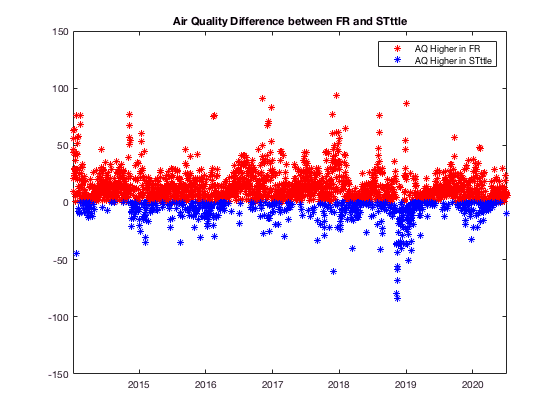


FR_Higher = zeros(length(diff), 1);
ST_Higher = zeros(length(diff), 1);

for i = 1:length(diff)
    if diff(i)>0
        FR_Higher(i) = diff(i);
        ST_Higher(i) = nan; 
    end 
    if diff(i)<0
        FR_Higher(i) = nan; 
        ST_Higher(i) = diff(i);
    end 
end 

plot(FR_AQ_Table.date, FR_Higher, '*r')
hold on; 
plot(ST_AQ_Table.date, ST_Higher, '*b')
ylim([-150 150])
title('Air Quality Difference between FR and STttle')
legend('AQ Higher in FR', 'AQ Higher in STttle')

function AQ_Table = AQ_table(filename)
    % Read file into a table 
    AQ_Table = readtable(filename);
    % Create an air quality column (Max value of all columns per day)
    AQ_Col = max([AQ_Table.pm25, AQ_Table.o3, AQ_Table.no2, AQ_Table.so2, AQ_Table.co], [], 2);
    AQ_Table.AQ = AQ_Col;
    % Change dates to matFRbs datetime object
    AQ_Table.date = datetime(AQ_Table.date,'InputFormat','yyyy/MM/dd');
    % Sort by date 
    [~,idx] = sort(AQ_Table.date, 'descend');
    AQ_Table = AQ_Table(idx,:);
end 

function [Table1_o Table2_o] = same_dates(Table1, Table2) 
    % Setting the length of both tables to that of the shorter table 
    max_len = min(length(Table1.date), length(Table2.date));
    Table1 = Table1(1:max_len, :);
    Table2 = Table2(1:max_len, :);
    
    Table1.date
    Table2.date
    % Finding all the common dates between both tables 
    [~, idx1, idx2] = intersect(Table1.date, Table2.date, 'stable')
    
    % Indexing the tables to only include common dates 
    Table1_o = Table1(idx1, :);
    Table2_o = Table2(idx2, :);
end 
